6.Choose Number of Topics for LDA Model

本示例说明了如何为LDA模型决定合适的主题数量。

可以将LDA模型的不同数量主题的拟合度进行比较。 

较低的困惑度代表较好的契合度。

% To reproduce the results of this example, set rng to 'default'.
rng('default')

1.Extract and Preprocess Text Data 

% 加载示例数据。
% 从event_narrative字段中提取文本数据。
filename = "proc_data.csv";
data = readtable(filename,'TextType','string');
textData = data.content;
% 文本清洗
documents = preprocessRMRB(textData);
documents(1:5)

ans =   5×1 tokenizedDocument:

     252 tokens: 百姓 人民 论坛 这代 百姓 农民 社会 道路 不能 全面 小康 大家 一起 参加 国政 经济 习近 总书 自己 陕北 黄土 贫苦 日子 岁月 百姓 发人 思考 过去 中国 巨轮 风雨 无阻 忧乐 百姓 政府 兹在 中心 议题 农村 贫困 人口 减少 支配 百姓 书写 温度 民生 故事 疫情 老人 出生 婴儿 患者 百姓 震撼 世界 生命 亿万 人民 满满 获得 稳稳 幸福 安全 人民 根本 宗旨 人民 中心 发展 思想 百姓 就是 百姓 时刻 心中 百姓 农功 思之 农业 社会 中国 传统 政治 思想 对于 强调 用心 土地 需要 日夜 才能 万斛 仓廪 为政 如此 朝暮 于民 事事 为民 才能 做到 为官 一任 一方 对于 产党 什么 百姓 百姓 什么 人民 心中 最高 位置 就是 保持 时时 放心 怀有 百姓 实际 人民 人民 满意 肚子 净颗 细粮 细粮 经常 挑着 扁担 习近 总书 谈起 几个 说明 这样 观点 保障 改善 民生 终点 连续 不断 起点 问题 全面 小康 胜利 放心 健康 人民 美好 生活 不断 攀升 需要 民生 改善 进一 百姓 百姓 具体 百姓 日子 幸福 百姓 实实 良心 需用 真心 需见 决战 决胜 剩下 硬骨 叠加 疫情 难上 集中 精力 以保 促稳 稳中 发展 需要 民生 需要 就业 减税 费约 亿元 不足 农民 纳入 常住 保障 新建 标准 农田 今年 政府 工作 报告 系列 民生 举措 见证 大国 民生 牵挂 激励 级党 政府 民生 工作 真正 百姓 变成 实际 天下 天下 天下 天下 赢得 疫情 胜利 还是 如期 全面 小康 社会 根本 动力 人民 百姓 民心 民力 亿万 人民 劲往 一定 战胜 一切 艰难 险阻 书写 无愧 时代 无愧 历史
    1108 tokens: 推动 社会 核心 价值 家庭 落地 以来 习近 总书 国家 发展 全局 促进 全面 发展 家庭 家教 发表 系列 重要 讲话 强调 家庭 家教 家庭 家教 人人 享有 人生 幸福 安康 社会 稳定 华民 伟大

% 随机留出10％的test文档。
numDocuments = numel(documents);
cvp = cvpartition(numDocuments,'HoldOut',0.1);
documentsTrain = documents(cvp.training);
documentsValidation = documents(cvp.test);
% 从training中创建一个词袋。 
% 删除总共出现不超过两次的单词。 
% 删除所有不包含任何单词的文档。
bag = bagOfWords(documentsTrain);
bag = removeInfrequentWords(bag,2);
bag = removeEmptyDocuments(bag);

2.Choose Number of Topics 

我们的目的是选择一定数量的主题，使模型困惑度最低。

但这不是唯一的考虑因素：适合大量主题的模型可能需要更长的时间才能收敛。综合二者的影响，需计算拟合优度和拟合时间。如果最佳主题数很高，那么您可能想要选择一个较低的值以加快拟合过程。

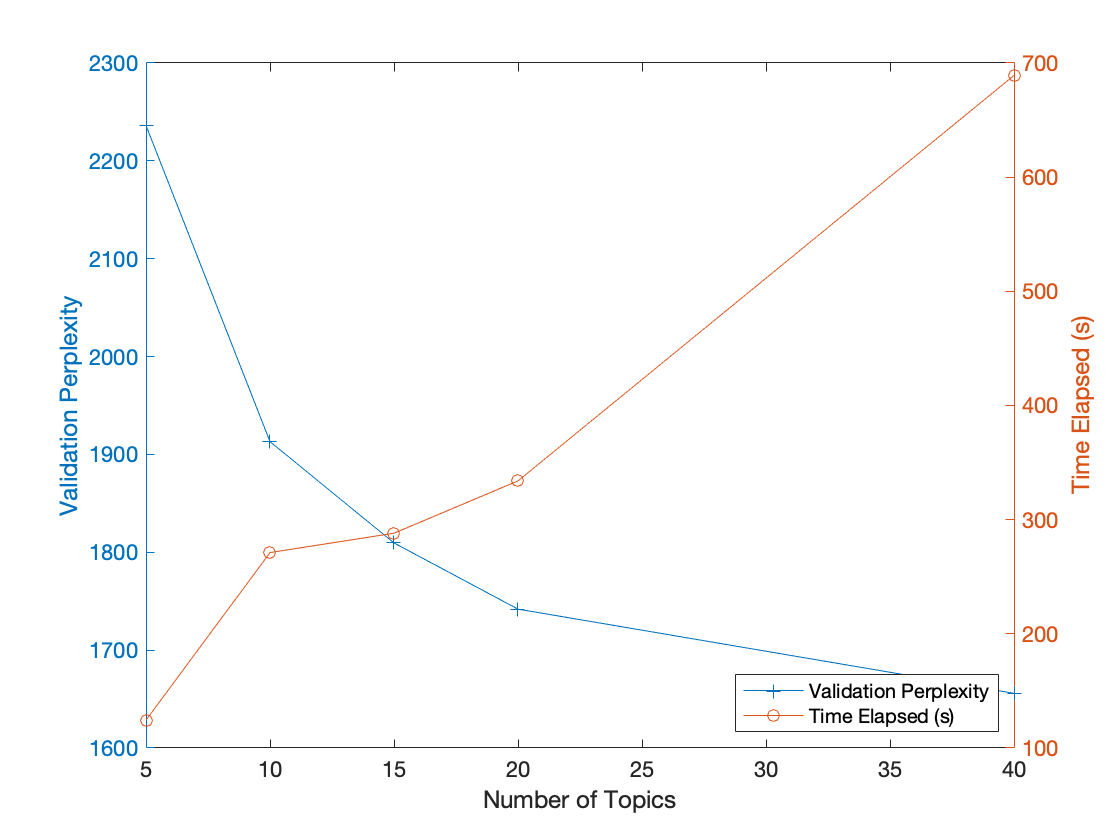

numTopicsRange = [5 10 15 20 40];
for i = 1:numel(numTopicsRange)
 numTopics = numTopicsRange(i);

 mdl = fitlda(bag,numTopics, ...
 'Solver','savb', ...
 'DataPassLimit',10,...
 'Verbose',0);

 [~,validationPerplexity(i)] = logp(mdl,documentsValidation);
 timeElapsed(i) = mdl.FitInfo.History.TimeSinceStart(end);
end
% 下图显示不同主题数量的困惑度和耗时。 
% 在左轴上绘制困惑度，在右轴上绘制时间。
figure
yyaxis left
plot(numTopicsRange,validationPerplexity,'+-')
ylabel("Validation Perplexity")
yyaxis right
plot(numTopicsRange,timeElapsed,'o-')
ylabel("Time Elapsed (s)")
legend(["Validation Perplexity" "Time Elapsed (s)"],'Location','southeast')
xlabel("Number of Topics")

该图表明，拟合具有10-20个主题的模型可能是一个不错的选择。其困惑度较低，且耗时合理。使用不同的主题数，会发现增加主题数量可以更好地拟合，但是拟合模型需要更长的时间才能收敛。